## [Data Gathering and Consolidation](https://apmonitor.com/pds/index.php/Main/GatherData)

### Reading Data

Gathering data is the process of consolidating disparate data (Excel  spreadsheet, CSV file, PDF report, database, cloud storage) into a  single repository. Data may reside in local storage or obtained through a remote connection to a database, web service, or extracted from a webpage.

Generate a data table **dx** and save it as a Comma Separated Values (CSV) file to be used as an example. 

tx = linspace(0, 1, 8); 
x = cos(tx); 
T = table(tx', x', 'VariableNames', {'Time', 'x'}); 

writetable(T, 'dx.csv', 'Delimiter', ','); 
disp(T) 

     Time         x   
    _______    _______

          0          1
    0.14286    0.98981
    0.28571    0.95946
    0.42857    0.90956
    0.57143    0.84113
    0.71429    0.75556
    0.85714     0.6546
          1     0.5403



An advantage of MATLAB is that it comes with many built-in functions. One such function is *readtable()*.

% read from local source
T1 = readtable('dx.csv'); 

% read from online source  
T2 = readtable('http://apmonitor.com/pds/uploads/Main/dx.txt'); 

Sometimes more control is needed to process complex data files. In these cases, the file can be opened and manipulated one line at a time. Here are some examples of ways the contents of a file can be read:

Display each line, one at a time, until the end of the file is reached.

% Open the file
fid = fopen('dx.csv', 'r'); 

% Read and display each line
while ~feof(fid)
    line = fgetl(fid); 
    disp(line) 
end

Time,x
0,1
0.142857142857143,0.989813260446615
0.285714285714286,0.959460581111917
0.428571428571429,0.909560351674167
0.571428571428571,0.841129213415236
0.714285714285714,0.755561346700697
0.857142857142857,0.654600066675268
1,0.54030230586814



% Close the file  
fclose(fid); 

Read the first 4 characters, one at a time.

% Open the file  
fid = fopen('dx.csv', 'r'); 

% Read the first 4 characters  
x = fread(fid, 4, 'char=>char'); disp(x) 

T
i
m
e



% Close the file  
fclose(fid); 

Manually read each line, one at a time (this could be put into a *for* loop to specify the quantity of lines to be read).

% Open the file  
fid = fopen('dx.csv', 'r'); 

% Read and display the first line  
line = fgetl(fid); 
disp(line) 

Time,x



% Read and display the second line  
line = fgetl(fid); 
disp(line) 

0,1



% Read and display the third line  
line = fgetl(fid); 
disp(line) 

0.142857142857143,0.989813260446615



% Close the file  
fclose(fid); 

### Joining Time-Series Data

For time series data, the tables are joined to match features and labels at particular time points. This is done by using the *innerjoin()* and *outerjoin()* functions. The innerjoin function combines only the rows of the two variables that share common time points, while the outerjoin function can be customized further.

tx = linspace(0,1,4); 
tx = tx.'

tx =          0
    0.3333
    0.6667
    1.0000


x = cos(tx); 
dx = table(tx,x,'VariableNames',{'Time','x'}); 

ty = linspace(0,1,3); 
ty = ty.'

ty =          0
    0.5000
    1.0000


y = sin(ty); 
dy = table(ty,y,'VariableNames',{'Time','y'}); 

z1 = innerjoin(dx,dy, "LeftKeys","Time","RightKeys","Time")

z1 = 2×3 table
    Time      x          y   
    ____    ______    _______

     0           1          0
     1      0.5403    0.84147


In the first two lines, the outerjoin function specifies the left time series to be used, while including the variable from the other dataset (switching the order of the datasets helps maintain "Time" as the leftmost column). The third line merges the two datasets at all time points.

z2 = outerjoin(dx,dy,"Type","left","RightVariables","y")

z2 = 4×3 table
     Time         x          y   
    _______    _______    _______

          0          1          0
    0.33333    0.94496        NaN
    0.66667    0.78589        NaN
          1     0.5403    0.84147


z3 = outerjoin(dy,dx,"Type","left","RightVariables","x")

z3 = 3×3 table
    Time       y         x   
    ____    _______    ______

      0           0         1
    0.5     0.47943       NaN
      1     0.84147    0.5403


z4 = outerjoin(dx,dy, "Keys","Time","MergeKeys",true)

z4 = 5×3 table
     Time         x          y   
    _______    _______    _______

          0          1          0
    0.33333    0.94496        NaN
        0.5        NaN    0.47943
    0.66667    0.78589        NaN
          1     0.5403    0.84147


### Appending Data

Multiple data sets can be combined with the *vertcat()* function. This is needed to combine multiple data sets with the same types of data but stored separately.

The new dataset is then passed through the *sortrows() *and *unique()* functions to chronologize the dataset and eliminate redundant rows. 

tx = linspace(0,1,4); 
x = cos(tx); 
dx = table(tx',x','VariableNames',{'Time','x'}); 

tx = linspace(0,1,3); 
x = cos(tx); 
dy = table(tx',x','VariableNames',{'Time','x'}); 

Full = vertcat(dx,dy); 
result = sortrows(Full,'Time');
result = unique(result,'rows','stable'); 
disp(result) 

     Time         x   
    _______    _______

          0          1
    0.33333    0.94496
        0.5    0.87758
    0.66667    0.78589
          1     0.5403



### Activity

Import Google Stock Data and display the table.

Calculate summary statistics such as the mean, median, standard  deviation, and quartile information. Create two new data columns for *Volatility=High-Low* and *Change=Close-Open*.

% stock ticker symbol   
url = 'http://apmonitor.com/pds/uploads/Main/goog.txt';  

% import data with readtable   
data = readtable(url,'VariableNamingRule','preserve'); 
data_array = table2array(data(:,2:end));

datamin = varfun(@min,data(:,2:end),"InputVariables",data(:,2:end).Properties.VariableNames)

datamin = 1×6 table
    min_Open    min_High    min_Low    min_Close    min_Adj Close    min_Volume
    ________    ________    _______    _________    _____________    __________

     917.42      922.08      909.7        915            915         8.883e+05 


datacmax = varfun(@max,data(:,2:end),"InputVariables",data(:,2:end).Properties.VariableNames)

datacmax = 1×6 table
    max_Open    max_High    max_Low    max_Close    max_Adj Close    max_Volume
    ________    ________    _______    _________    _____________    __________

      980        990.71     976.11      989.25         989.25        2.5054e+06


datacount = varfun(@numel,data(:,2:end),"InputVariables",data(:,2:end).Properties.VariableNames)

datacount = 1×6 table
    numel_Open    numel_High    numel_Low    numel_Close    numel_Adj Close    numel_Volume
    __________    __________    _________    ___________    _______________    ____________

        23            23           23            23               23                23     


datamean = varfun(@mean,data(:,2:end),"InputVariables",data(:,2:end).Properties.VariableNames)

datamean = 1×6 table
    mean_Open    mean_High    mean_Low    mean_Close    mean_Adj Close    mean_Volume
    _________    _________    ________    __________    ______________    ___________

     942.25        948.9       936.86       944.36          944.36        1.3447e+06 


datamedian = varfun(@median,data(:,2:end),"InputVariables",data(:,2:end).Properties.VariableNames)

datamedian = 1×6 table
    median_Open    median_High    median_Low    median_Close    median_Adj Close    median_Volume
    ___________    ___________    __________    ____________    ________________    _____________

        933          938.38         927.74         935.09            935.09           1.267e+06  


datastd = varfun(@std,data(:,2:end),"InputVariables",data(:,2:end).Properties.VariableNames)

datastd = 1×6 table
    std_Open    std_High    std_Low    std_Close    std_Adj Close    std_Volume
    ________    ________    _______    _________    _____________    __________

     19.904      21.502     20.366      21.906         21.906        4.2399e+05


dataquantile = array2table(quantile(data_array,[0.25,0.50,0.75]),"VariableNames" ...
    ,data(:,2:end).Properties.VariableNames, "RowNames",["25%" "50%" "75%"])

dataquantile = 3×6 table
            Open      High      Low      Close     Adj Close      Volume  
           ______    ______    ______    ______    _________    __________

    25%    926.02    932.95    922.46    925.96     925.96      1.0284e+06
    50%       933    938.38    927.74    935.09     935.09       1.267e+06
    75%    956.62       962    951.31    958.78     958.78       1.571e+06


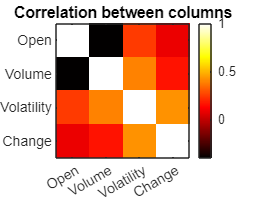



% calculate change and volatility   
data.Change = data.Close - data.Open;   
data.Volatility = data.High - data.Low;   
analysis = {'Open','Volume','Volatility','Change'};  
corr_data = corr(table2array(data(:,analysis))); 

% Plot heatmap 
imagesc(corr_data)
colormap('hot')
colorbar;
xticks(1:4)
xticklabels(analysis)
yticks(1:4)
yticklabels(analysis)
title('Correlation between columns'); 